# Exercise Session1-200916

## Part 1: Data, data everywhere

clc;
clear;
close all;

load fisheriris
disp("Display first 10 lines");

Display first 10 lines


disp(meas(1:10,:));

    5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000
    5.4000    3.9000    1.7000    0.4000
    4.6000    3.4000    1.4000    0.3000
    5.0000    3.4000    1.5000    0.2000
    4.4000    2.9000    1.4000    0.2000
    4.9000    3.1000    1.5000    0.1000


size(meas);

disp(unique(species))

    'setosa'
    'versicolor'
    'virginica'


## Part 2: Data Manipulation

#### **Accessing data**

[X, y] = pick(10, meas, species);
[X, y] = pick([1,2,3,4], meas, species);

可以输入logical array用于选择想要的species，如 species=="setosa"

idx = (repmat(1:2,1,75) == 1);

repmat(A, r1, r2, ...)代表的是向r1和r2方向分别重复对应的次数。示例如下

repmat(1:2,1,2)

ans =

     1     2     1     2

[X, y] = pick(idx, meas, species);
[X, y] = pick(species=="setosa", meas, species);

### **Sorting and shuffling data**

使用randperm进行随机代换，[`p = randperm(n)`](https://www.mathworks.com/help/matlab/ref/randperm.html#d120e1018184)

returns a row vector containing a random permutation of the integers from 1 to `n` without repeating elements.

idx = randperm(length(meas));
X = meas(randperm(length(meas)),:);
y = species(randperm(length(species)),:);

sort则是直接进行排序，文字从a到z，数字从小到大

y = sort(y);
X = sort(X);

(X-meas) < 1e-4;

增加额外的一行以用于记住原有的index

X = [[1:length(meas)].', meas];

#### Data slicing

ratio = 0.5;
[X1, y1, X2, y2] = split_dataset(meas, species, ratio);
length(X1) == ratio * length(meas);
(sort(meas) - sort([X1;X2])) < 1e-4;

% 上面对应的结果就是一个=1的逻辑矩阵，似乎用断言也会失败assert((sort(meas) - sort([X1;X2])) < 1e-4)

错误使用 assert

条件输入参数必须为标量逻辑值。 

其他示例：

>> a=ones(2)

a =

     1     1

     1     1

>> b=ones(2)

b =

     1     1

     1     1

>> assert(a==b)

错误使用 assert

条件输入参数必须为标量逻辑值

## Part 3 Categorical and numerical data

unique(species)

ans = 3×1 cell 数组
    {'setosa'    }
    {'versicolor'}
    {'virginica' }

string(species{42}) % 由cell array转为string array

ans = "setosa"

grp2idx本质的功能就是从一堆数据中找到不同的类别，然后根据出现的不同顺序标上label

testSample = {'a', 'a', 'b', 'c', 'a'}

testSample =

  1×5 cell 数组

    {'a'}    {'a'}    {'b'}    {'c'}    {'a'}

grp2idx(testSample)

ans =

     1

     1

     2

     3

     1

grp2idx(species);
length(unique(grp2idx(species))) == 3

ans = logical
   1

挑选一个case进行测试

% idx = 75;
% categories = grp2idx(species);
% unique_categories = unique(species);
% species(idx) == string(unique_categories(categories(idx)))

idx = 25;
categories = hyj_grp2idx(species);
unique_categories = unique(species);
species(idx) == string(unique_categories(categories(idx)))

ans = logical
   1

## Part 4 Data visualization

X = meas;
y = hyj_grp2idx(species);
unique(y)

ans =      1
     2
     3



labels = {'sepal length','sepal width','petal length','petal width'};
pairs = combnk(1:4,2)

pairs =      3     4
     2     4
     2     3
     1     4
     1     3
     1     2


**Extract all the features corresponding to a specific type of flowers and store the results in** `Xsetosa`**,** `Xversicolor` **and** `Xvirginica`

[Xsetosa, ~] = pick(species == "setosa", meas, species);
[Xversicolor, ~] = pick(species == "versicolor", meas, species);
[Xvirginica, ~] = pick(species == "virginica", meas, species);

首先是简单plot

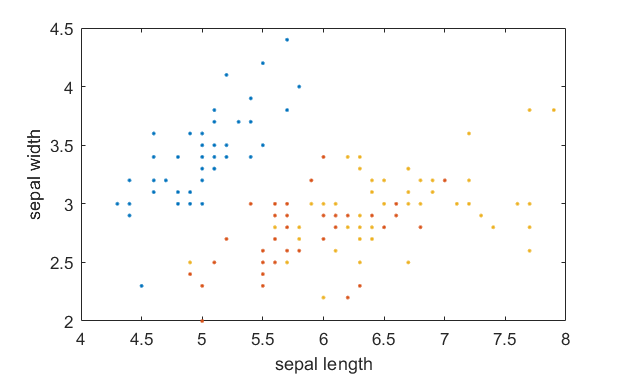

figurePlot = figure(1); % figure with different index
set(figurePlot,'position',[0 0 500 300]); % size
plot([Xsetosa(:,1) Xversicolor(:,1) Xvirginica(:,1)],...
     [Xsetosa(:,2) Xversicolor(:,2) Xvirginica(:,2)], '.')
xlabel(labels{1})
ylabel(labels{2})

**Write a function that plot the 6 figures corresponding to visualization of each features taken 2 by 2**

`plot2dsamples``(``Xsetosa``,` `Xversicolor``,` `Xvirginica``,` `pairs``,` `labels``)`

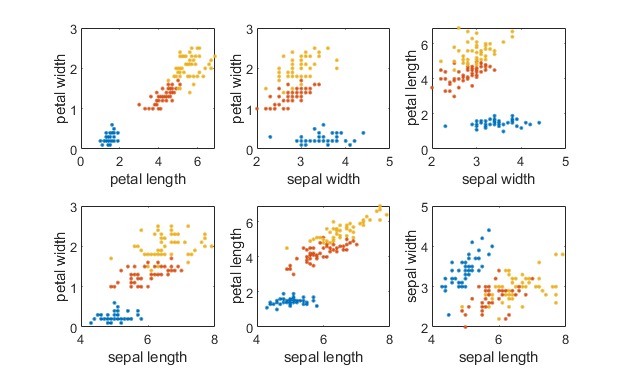

plot2dsamples(Xsetosa, Xversicolor, Xvirginica, pairs, labels)

**histogram** 

直接画出三种不同品种的直方统计图

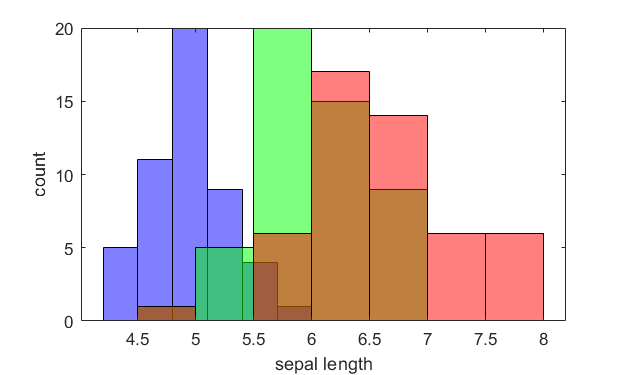

figureHist = figure(2); % figure with different index
set(figureHist,'position',[0 0 500 300]); % size
histogram(Xsetosa(:,1), 'FaceAlpha', .5, 'FaceColor', 'b');
hold on
histogram(Xversicolor(:,1), 'FaceAlpha', .5, 'FaceColor', 'g');
hold on
histogram(Xvirginica(:,1), 'FaceAlpha', .5, 'FaceColor', 'r');
xlabel(labels{1})
ylabel("count")

**Write a function that plots the histograms of all the features**

`plothistogram``(``Xsetosa``,` `Xversicolor``,` `Xvirginica``,` `labels``)`

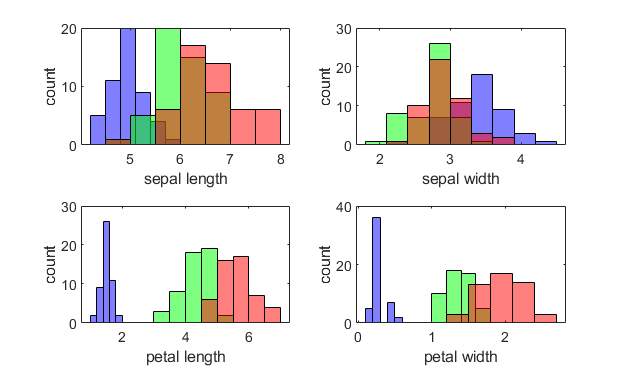

plothistogram(Xsetosa, Xversicolor, Xvirginica, labels)

Another way to look at this is to use `boxplot` plots. Those are interesting as they give some insights on wether or not the differences between species on a specific feature could be significant or not.

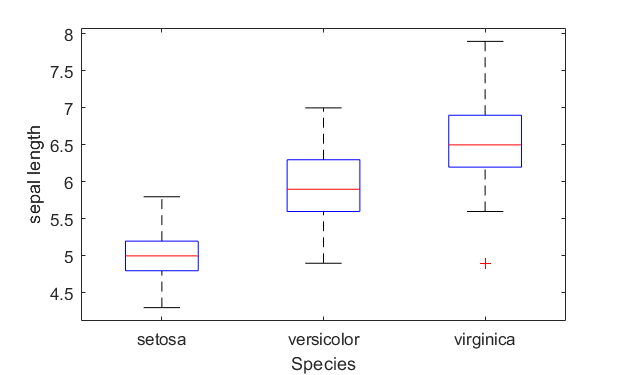

figureBox = figure(3); % figure with different index
set(figureBox,'position',[0 0 500 300]); % size
boxplot(X(:,1), species)
xlabel('Species')
ylabel(labels(1))

**Write a function that show the boxplots of all the features**

`plotboxplots``(``X``,` `species``,` `labels``)`

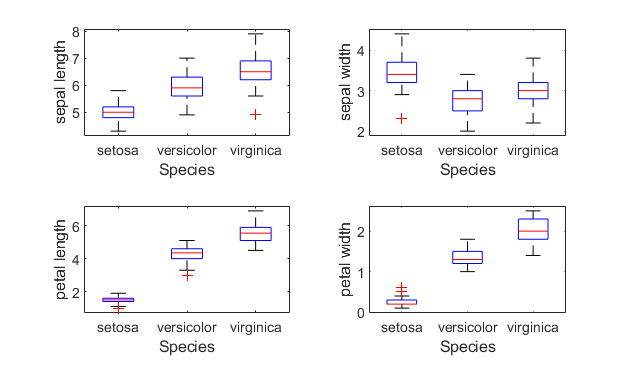

plotboxplots(X, species, labels)